# DSP Assignment 2

Samuel Stark (sws35)

November 2021

### 2(a)

256-sample window produces a 256-sample DFT that is hermetian-symmetric (for a real-valued input signal) (see [https://dsp.stackexchange.com/a/4843](https://dsp.stackexchange.com/a/4843) )

=> DFT[m] = DFT[256-m]

Bucket maximized when signal $\sin \left(2\pi f*\frac{i}{f_s }\right)\mathrm{matches}\;e^{-\mathrm{j2}\pi \frac{i}{n}k}$


$$\begin{array}{l}
2\pi \frac{i}{n}k=2\pi f*\frac{i}{n}*\frac{n}{f_s }\\
k_{\mathrm{single}} =\frac{f*n}{f_s }
\end{array}$$


For 941Hz $k_{\mathrm{single941}} =\frac{941*256}{8000}=30\ldotp 1120$

For 1336Hz $k_{\mathrm{single1336}} =\frac{1336*128}{8000}=42\ldotp 7520$

=> Final peaks


$$\begin{array}{l}
k_{\mathrm{double941}} =30,\;256-30=30,226\\
k_{\mathrm{double1336}} =43,256-43=43,213
\end{array}$$


Example below:

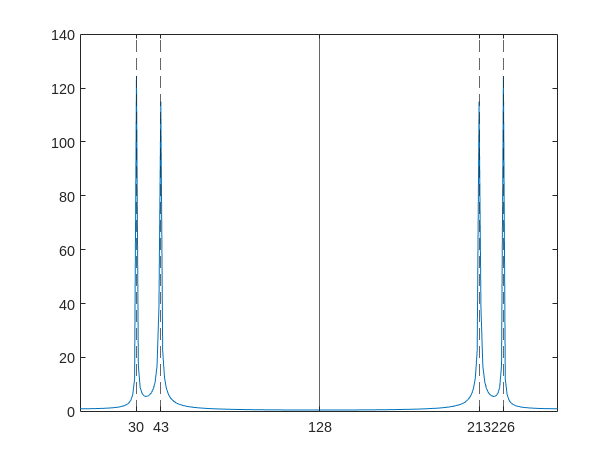

Fs=8000;
n=256;
% n time samples spaced by 1/Fs
ts = (1/Fs):(1/Fs):(n/Fs);
x = sin(2*pi*941*ts)+sin(2*pi*1336*ts);
X = fft(x);
plot(0:255, abs(X))
xline(128)
xline([30 43 (256-43) (256-30)], '--')
xticks([30 43 128 (256-43) (256-30)])
xlim([0 255])

### 2(b)

% Determine sampling frequency
[y_original, Fs] = audioread('touchtone-synth.wav');

% Choose good window size
% Started with 320, to get 50Hz between buckets (16000/50 = 320)
% Didn't separate well enough, so tried 512 then 1024.
window_size = 1024; 

% Each block has to overlap with another block by 50%
% => ranges are 1-512, 256-768...
% Pad the edges out by window_size/2 - this ensures all real samples are
% covered by two windows.
% Pad the far edge out a farther in case the length isn't divisible
% by window_size.
y = [zeros(window_size/2,1); y_original; zeros(window_size,1)];
block_starts = 1:(window_size/2):(length(y)-window_size);
N = length(block_starts);
blocks = zeros(window_size,N);
for i = 1:N
    data = y(block_starts(i):block_starts(i)+window_size-1);
    blocks(1:end,i) = data;
end

% Choose a window:
% Maximum frequency we need to find is 1633Hz, Fs is 16000Hz
% Choose Hamming, because it doesn't have as steep a falloff as Hann
w = hamming(window_size);
windowed_blocks = zeros(window_size,N);
for i = 1:N
    windowed_blocks(1:end,i) = blocks(1:end,i) .* w;
end

% Compute FFTs
dfts = fft(windowed_blocks, window_size);

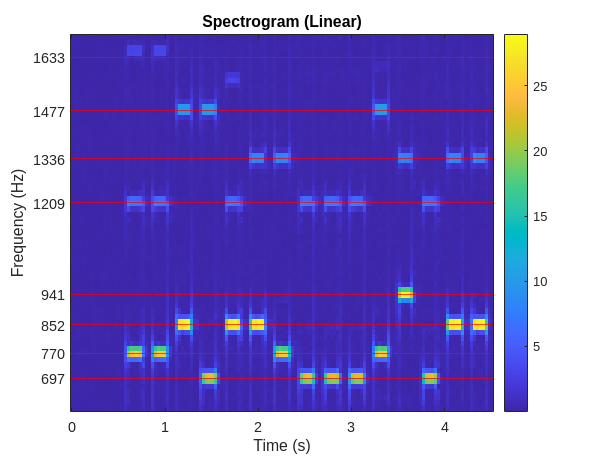

% Discard negative frequencies, take amplitude
dft_posf_amp = zeros(window_size/2,N);
for i = 1:N
    % select first half of dft values => only the positive frequencies
    dft_posf_amp(1:end,i) = abs(dfts(1:(window_size/2), i));
end

% t = 0 to (final sample number / frequency)
image_xrange = [0, block_starts(end)/Fs];
% f = 0 to Fs/2
image_yrange = [0, Fs/2];

% Produce a spectrogram
image(image_xrange, image_yrange, ...
    dft_posf_amp, 'CDataMapping','scaled')
colorbar
% Limit to the frequency range we care about
ylim([600 1700])
% Mark important frequencies
yticks([697 770 852 941 1209 1336 1477 1633])
yline([697 770 852 941 1209 1336 1477 1633], 'r')
% Make the frequencies go bottom to top
set(gca, 'YDir','normal')
ylabel("Frequency (Hz)")
xlabel("Time (s)")
title("Spectrogram (Linear)")

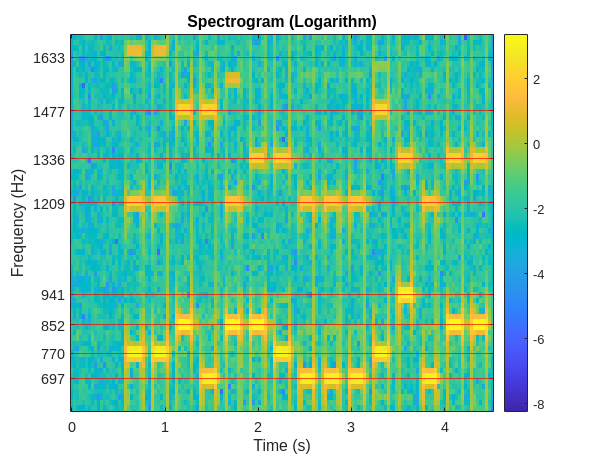


% Logarithmic version
image(image_xrange, image_yrange, ...
    log(dft_posf_amp), 'CDataMapping','scaled')
colorbar
ylim([600 1700])
yticks([697 770 852 941 1209 1336 1477 1633])
yline([697 770 852 941 1209 1336 1477 1633], 'r')
set(gca, 'YDir','normal')
ylabel("Frequency (Hz)")
xlabel("Time (s)")
title("Spectrogram (Logarithm)")

Numbers:

770x1209, 770x1209, 852x1477, 697x1477, 852x1209, 852x1336, 770x1336, 697x1209, 697x1209, 697x1209, 770x1477, 941x1336, 697x1209, 852x1336, 852x1336

= 449378511160188

### 2(c)

Design band-pass filters

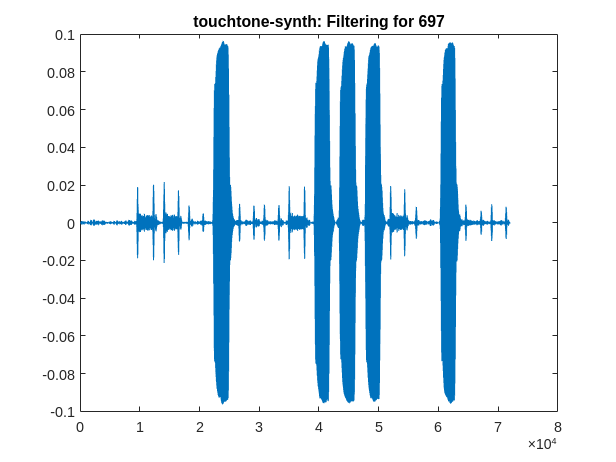

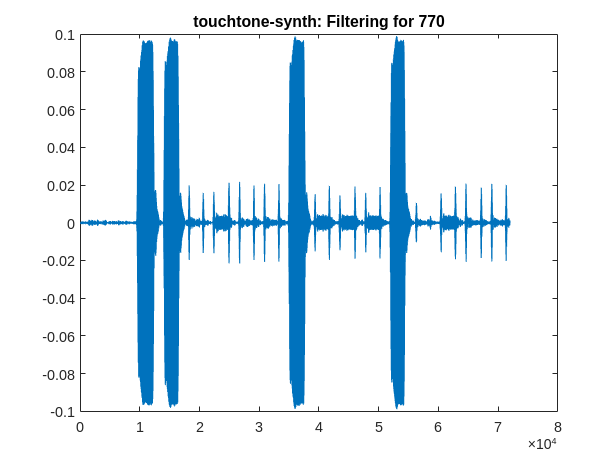

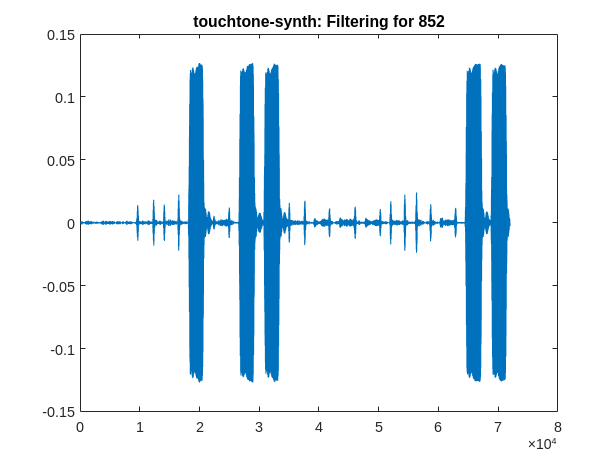

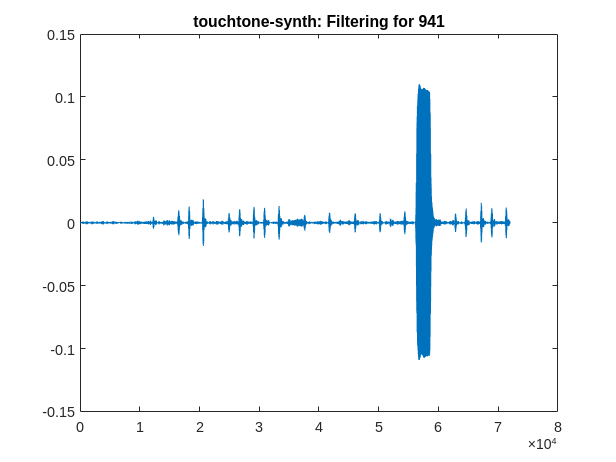

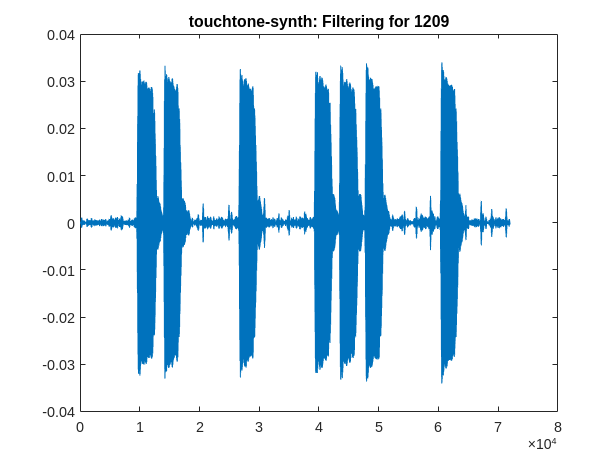

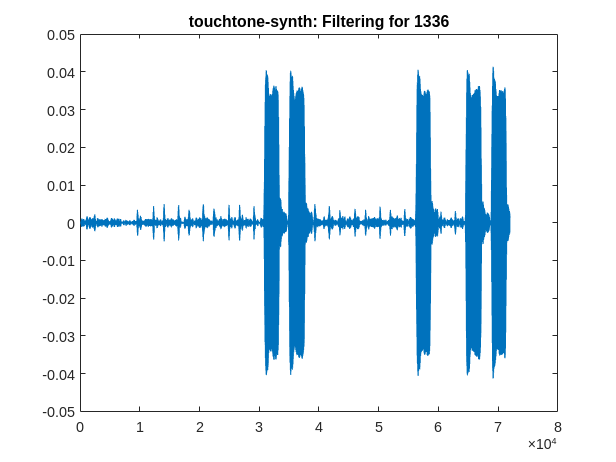

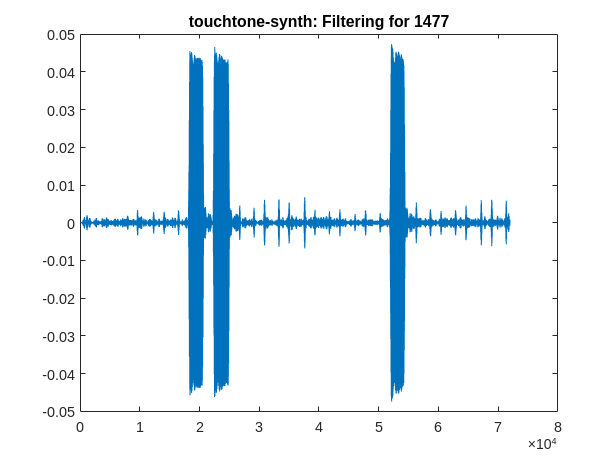

freqs = [697 770 852 941 1209 1336 1477]; % Exclude 1633
% Band should be f +- 1.8%
freqs_pass_low = freqs * (1.0 - 0.018);
freqs_pass_high = freqs * (1.0 + 0.018);

fir_order = 400;
% 1 for yes, 0 for no
show_freq_response = 0;
show_filtered_y = 1;
stack_all_tones = 1;
y = y_original;

for i = 1:length(freqs)
    b = fir1(fir_order, (2/Fs)*[freqs_pass_low(i) freqs_pass_high(i)]);
    a = [1];

    if show_freq_response
        figure;
        title("Response for filter for " + freqs(i));
        freqz(b, a, 512, Fs);
    end

    if show_filtered_y
        figure;
        plot(filter(b, a, y));
        title("touchtone-synth: Filtering for " + freqs(i));
    end
end

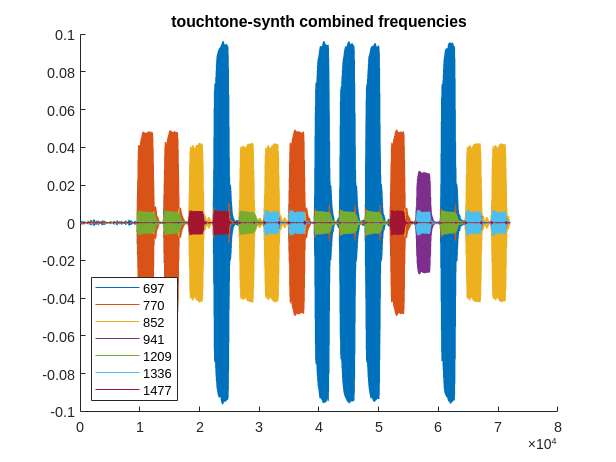

if stack_all_tones
    figure;
    hold on;
    for i = 1:length(freqs)
        b = fir1(fir_order, (2/Fs)*[freqs_pass_low(i) freqs_pass_high(i)]);
        a = [1];
        plot(filter(b, a, y)/i);
    end
    title(["touchtone-synth combined frequencies"]);
    legend(string(freqs), 'Location','southwest');
    hold off;
end

The final plot shows each frequency (scaled so that higher frequencies are smaller), and the colors on the combined graph show which tones were dialled.

### 2(d)

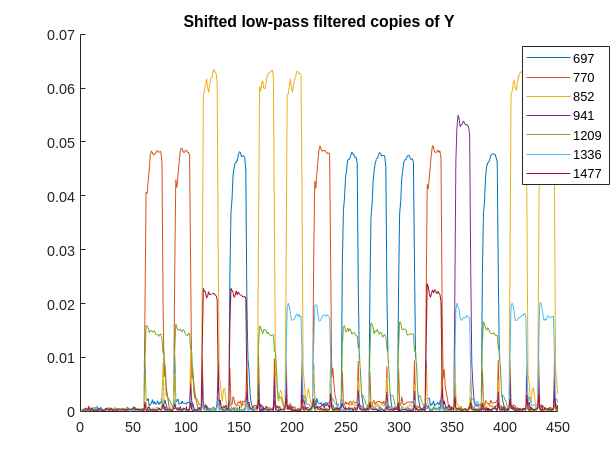

low_pass_fir_order = 400;
% Only enable one at a time
show_alias_check = 0;
show_complete_figure = 1;

if show_complete_figure
    figure;
    complete_figure = gca;
end

for i = 1:length(freqs)
    % Multiply each waveform by a complex phasor
    phasor = exp(-2*pi*1i*freqs(i)*(1:length(y_original))/Fs);
    shifted_y = y_original .* phasor';
    
    % Apply a low-pass filter to let in 0Hz +- 1.8% of freqs(i)
    % low-pass = pass frequencies lower than X
    % => low-pass filter for freqs(i) * 1.8%
    b = fir1(low_pass_fir_order, freqs(i) * 0.018 * 2/Fs);
    a = [1];
    shifted_filtered_y = filter(b, a, shifted_y);
    
    % Reduce the sampling rate to 100Hz
    % Original is 16000 => keep every 16000/100 = 160th sample
    %
    % I tried checking for aliasing by visually inspecting and comparing
    % waveforms, but I don't think that's the right way to do it.
    % The right way would probably involve looking at the FFTs, but I 
    % don't have enough time to do that right now. Sorry!
    reduced_shifted_filtered_y = shifted_filtered_y(1:(Fs/100):end);

    if show_alias_check
        figure;
        hold on;
        % Plot both on the same axes
        plot(abs(shifted_filtered_y));
        plot(1:(Fs/100):length(shifted_filtered_y), ...
            abs(reduced_shifted_filtered_y));
        hold off;
    end

    if show_complete_figure
        hold (complete_figure, "on");
        plot(abs(reduced_shifted_filtered_y));
        hold (complete_figure, "off");
    end
end

if show_complete_figure
    hold (complete_figure, "on");
    % position legend so it doesn't block graph
    % From https://stackoverflow.com/a/3602614
    h = legend(string(freqs));
    pos = get(h, 'position');
    set(h, 'position', [0.85, 0.6, pos(3:4)]);
    % Set title
    title("Shifted low-pass filtered copies of Y")
    hold (complete_figure, "off");
end

As before, the colors on the combined graph show which frequencies are used for each press.

770x1209, 770x1209, 852x1477, 697x1477, 852x1209, 852x1336, 770x1336, 697x1209, 697x1209, 697x1209, 770x1477, 941x1336, 697x1209, 852x1336, 852x1336

= 449378511160188